# Hands-On: Response Modes, Eigenvectors & the State Free Movement 

## Introduction

Consider the LTI discrete-time system


$$\left\{ \begin{array}{rcl}
x(k+1) &=& A\, x(k) + B \, u(k) \\
y(k) &=& C\,x(k)
\end{array} \right.$$


and suppose that all the eigenvalues of the $A$matrix are all distinct. 

We know (please refer to the class material in "*Lecture 3 *" and to the [live script dealing with response modes](matlab:open('./LTI_movements_response_modes.mlx'))) that in this scenario it is possible to compute the response mode matrices exploiting the left and right eigenvectors of $A$.

What you will learn in this live script is:

- How to select a proper initial state, with the aim to influence the whole state free movement, using left and right eigenvectors of the $A$matrix.

clear
close all
clc
sympref('HeavisideAtOrigin',1); % initial setting

## Application Example

Consider the LTI discrete-time system


$$\left\{ \begin{array}{rcl}
x(k+1) &=& A\, x(k) + B \, u(k) \\
y(k) &=& C\,x(k)
\end{array} \right.$$


where 

$A = \left[ \begin{array}{ccc}
                0 & 1 & 0 \\
               1 &0 & 0 \\
               1 & 1 & 0
\end{array} \right]$ , $B = \left[ \begin{array}{c}
                5 \\
              -4\\
               -3
\end{array} \right]$, $C = \left[ \begin{array}{ccc}
                -1 & 1 & 4
\end{array} \right]$

Let us start assigning the matrices (please note: this time we do not declare the matrix as a symbolic variable)

n = 3; % state dimension
Ts = 1; % we need a discrete-time periiod to simulate the system response
B = [5;-4;-3]; C = [-1, 1, 4]; D = 0;
A = [0, 1, 0; ...
     1,  0, 0; ...
      1, 1, 0]

A =      0     1     0
     1     0     0
     1     1     0


Then let's compute the eigenvalues and the corresponding eigenvectors

[eigV, lambda] = eig(A)

eigV =          0    0.4082    0.7071
         0    0.4082   -0.7071
    1.0000    0.8165         0


lambda =      0     0     0
     0     1     0
     0     0    -1


% extracting the main diagonal from the square matrix lambdaSET, creating
% a column vector and assigning the col. vector to lambdaSET
lambda = diag(lambda) 

lambda =      0
     1
    -1


How many distinct eigenvalues?

numel(unique(lambda))

ans = 3

How many independent eigenvectors correspond to each distinct eigenvalue?

rank(eigV)

ans = 3

The algebraic and the geometric multiplicity of each eigenvalue are equal each other and equal to one. So the matrix A does admit diagonal form.

### State Movement & Right Eigenvectors

It is well known that, when the eigenvalues of the matrix $A$are all distinct, the state free movement starting from a generic initial state $x_0$ can be expressed as (refer to the class material, L3-p. 20)


$$x(k) = A^k x_0
=  v_1 \tilde v_1^{\top} \, x_0 \, \lambda_1^k +
\cdots +
v_n \tilde v_n^{\top}\,  x_0 \, \lambda_n^k$$


where $v_i$ and $\tilde{v}_j^{\top}$are respectively the i-th right eigenvector and the j-th left one (refer also to the [live script on the response modes](matlab:open('./LTI_movements_response_modes.mlx'))).

Here, we want to experiment with what happens if the initial state is a linear combination of a subset of the right eigenvector set.

#### Picking Some Eigenvectors

Select some of the right eigenvectors to generate an initial state: 

pickingV1 = false;
pickingV2 = true;
pickingV3 = true;

% se scelgo uno solo, i movimenti dello stato sono in una  retta
% se ne scelgo due vengono allineati lungo un piano

theChosenOnes = [pickingV1, pickingV2, pickingV3]

theChosenOnes = 1×3 logical array
   0   1   1


#### A Random Linear Combination

Based on the selection, random numbers are generated to be used to linearly combine the chosen vectors

Ntrials = 215; % let's generate Ntrials free movements
% Please, note: to see different colors in the plots, correspondiing to each different trial,
% Ntrials should be less or equal to 6
how_many = sum(theChosenOnes);
LinCoeffs = zeros(n,Ntrials);
LinCoeffs(theChosenOnes,:) = randn(how_many, Ntrials)

LinCoeffs =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -1.3712    0.2041    0.6636   -0.2128    0.4582   -1.0549    0.1291   -0.0301    0.5963    0.8070   -0.0063   -0.9212   -0.9612   -0.2002    0.3492    0.9271   -0.3272    0.2882   -0.0479    0.4441    0.0494    0.3082   -0.1972   -0.1031    0.3933   -1.2976    0.6210   -1.6794   -0.6543   -1.2923    0.2417    0.4676   -0.2298    0.4805    0.4216   -2.2493   -0.6321    1.5516    0.1769   -0.2146    0.3309    1.0905   -0.4385   -0.0584    0.4386   -0.8377    0.7941    0.6492    0.8

The generated initial state $x_0$is 

x0 = eigV*LinCoeffs

x0 =    -0.5525   -0.2073    0.4305   -0.1180   -0.1251   -0.5407    0.4129   -0.3357    0.1632    0.2660   -0.0675   -1.0315    0.8696    0.5832    1.4573   -0.4891    0.4969    1.7194   -1.1169   -0.4635    0.7825    0.3377   -0.1841   -2.0213    0.8608   -1.6060   -0.8125   -0.1277    0.6132   -0.9620    0.4871    0.3263   -0.5034   -0.0774    0.9412    0.3577    0.6728   -0.4052    2.5233    0.2562    1.0316   -0.2240    0.0637    1.7687    0.4884   -1.2665    0.1847   -0.3229   -0.9166    1.2382
   -0.5671    0.3740    0.1112   -0.0558    0.4992   -0.3207   -0.3075    0.3111    0.3237    0.3930    0.0624    0.2794   -1.6545   -0.7467   -1.1722    1.2461   -0.7641   -1.4841    1.0778    0.8260   -0.7421   -0.0861    0.0230    1.9371   -0.5397    0.5464    1.3195   -1.2435   -1.1474   -0.0932   -0.2898    0.0555    0.3158    0.4697   -0.5970   -2.1942   -1.1889    1.6721   -2.3788   -0.4315   -0.7615    1.1144   -0.4217   -1.8163   -0.1303    0.5826    0.4637    0.8530    1.6481    

#### Evaluating the Free Movement

Assign a time horizon for the computatiion of the state movement

Thorizon = 10;

Let's compute the state movement starting from $x_0$

sysD = ss(A, B, C, D, Ts); % the discrete-time dynamical system

Ydata = cell(Ntrials, 1); % data structures used to store  respectively output Y, 
Xdata = cell(Ntrials, 1); % state X and time T data, obtained for each different
Tdata = cell(Ntrials, 1); % free movement

for k=1:Ntrials
    [Y, T, X ] = initial(sysD, x0(:,k), Thorizon);
    % Ntrials simulation, each starting from a different initial state
    Ydata{k} = Y;
    Xdata{k} = X;
    Tdata{k} = T;
end % for k

#### Plotting the State Movement

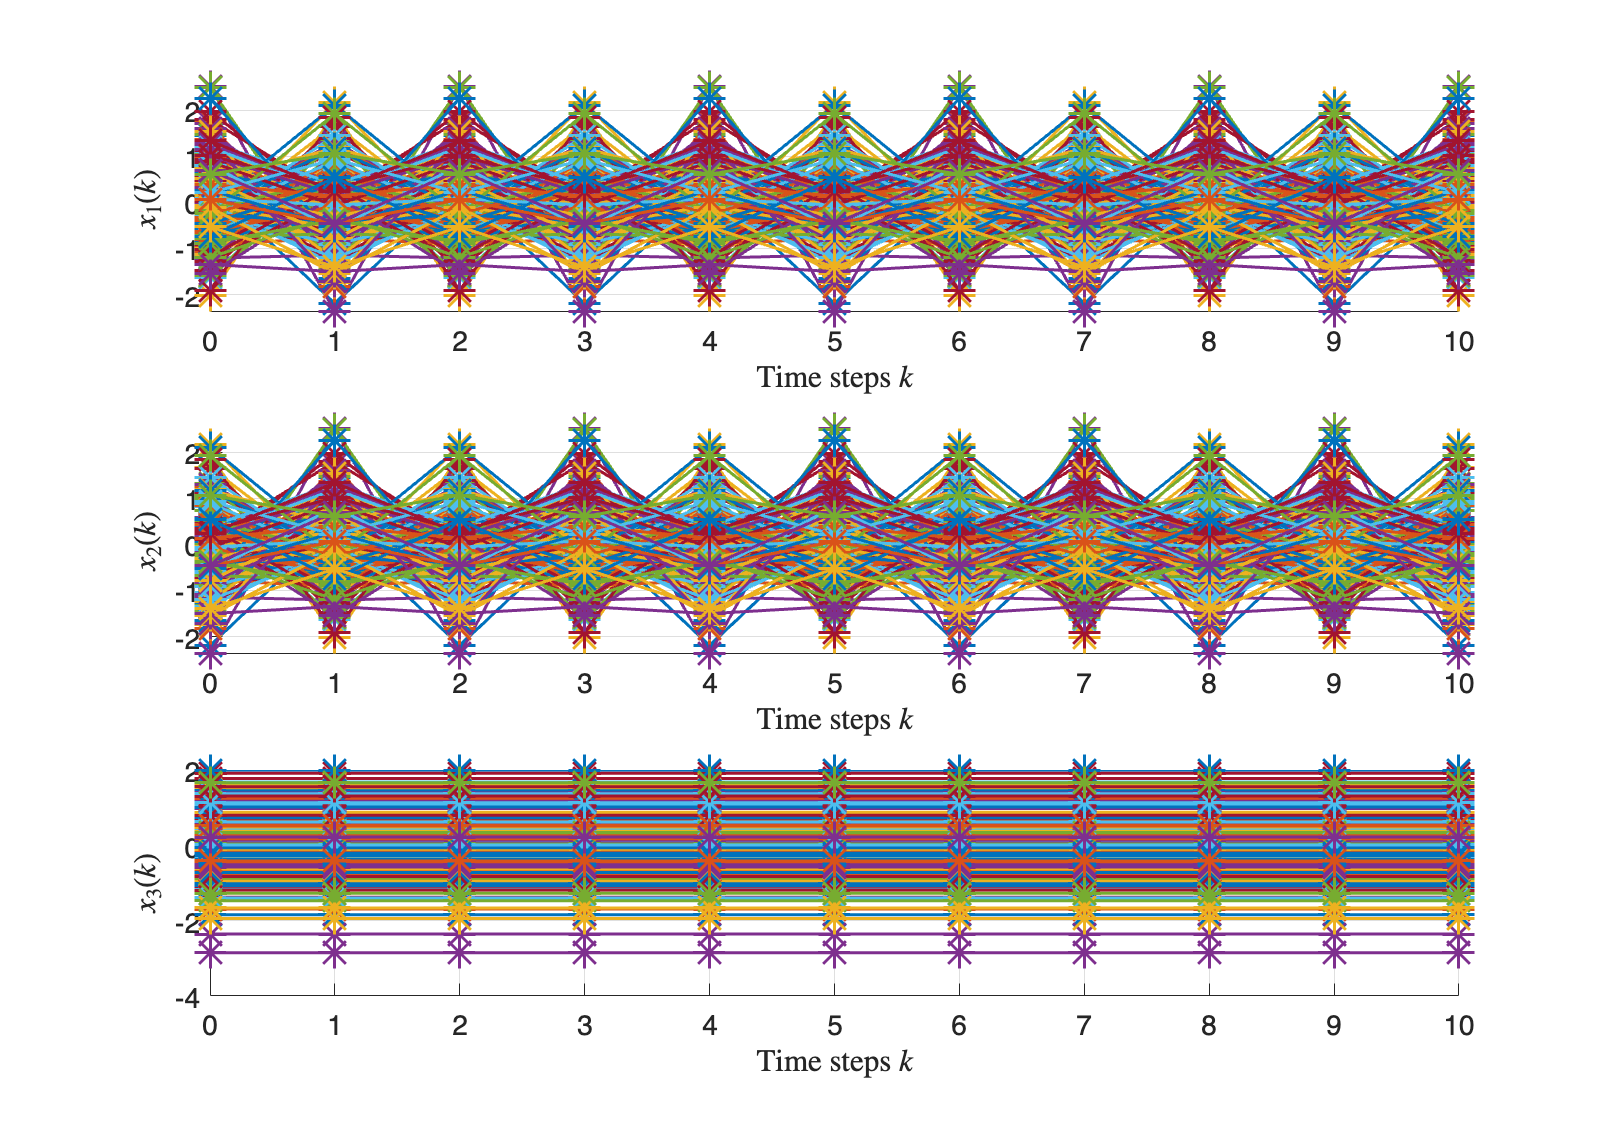

figure('Units','normalized', 'Position',[ 0.1, 0.1, 0.75, 0.85]);
hp1 = subplot(3,1,1);hold on; grid on;
hp2 = subplot(3,1,2);hold on; grid on;
hp3 = subplot(3,1,3);hold on; grid on;

for k=1:Ntrials
    Xvar = Xdata{k}; % retrieving the data from the storage set
    Tset = Tdata{k};
    plot(hp1, Tset, Xvar(:,1), 'LineStyle','-','LineWidth',1.5,'Marker','*','MarkerSize',16);
    plot(hp2, Tset, Xvar(:,2), 'LineStyle','-','LineWidth',1.5,'Marker','*','MarkerSize',16);
    plot(hp3, Tset, Xvar(:,3), 'LineStyle','-','LineWidth',1.5,'Marker','*','MarkerSize',16);
end % for k
hold off;
grid on; 
xlabel(hp1,'Time steps $k$', 'Interpreter','latex'); 
ylabel(hp1,'$x_1(k)$', 'Interpreter','latex'); 
set(hp1, 'Fontsize', 14);

xlabel(hp2, 'Time steps $k$', 'Interpreter','latex'); 
ylabel(hp2,'$x_2(k)$', 'Interpreter','latex'); 
set(hp2, 'Fontsize', 14);

xlabel(hp3,'Time steps $k$', 'Interpreter','latex'); 
ylabel(hp3,'$x_3(k)$', 'Interpreter','latex'); 
set(hp3, 'Fontsize', 14);

Let's view the state evolution in a 3D drawing

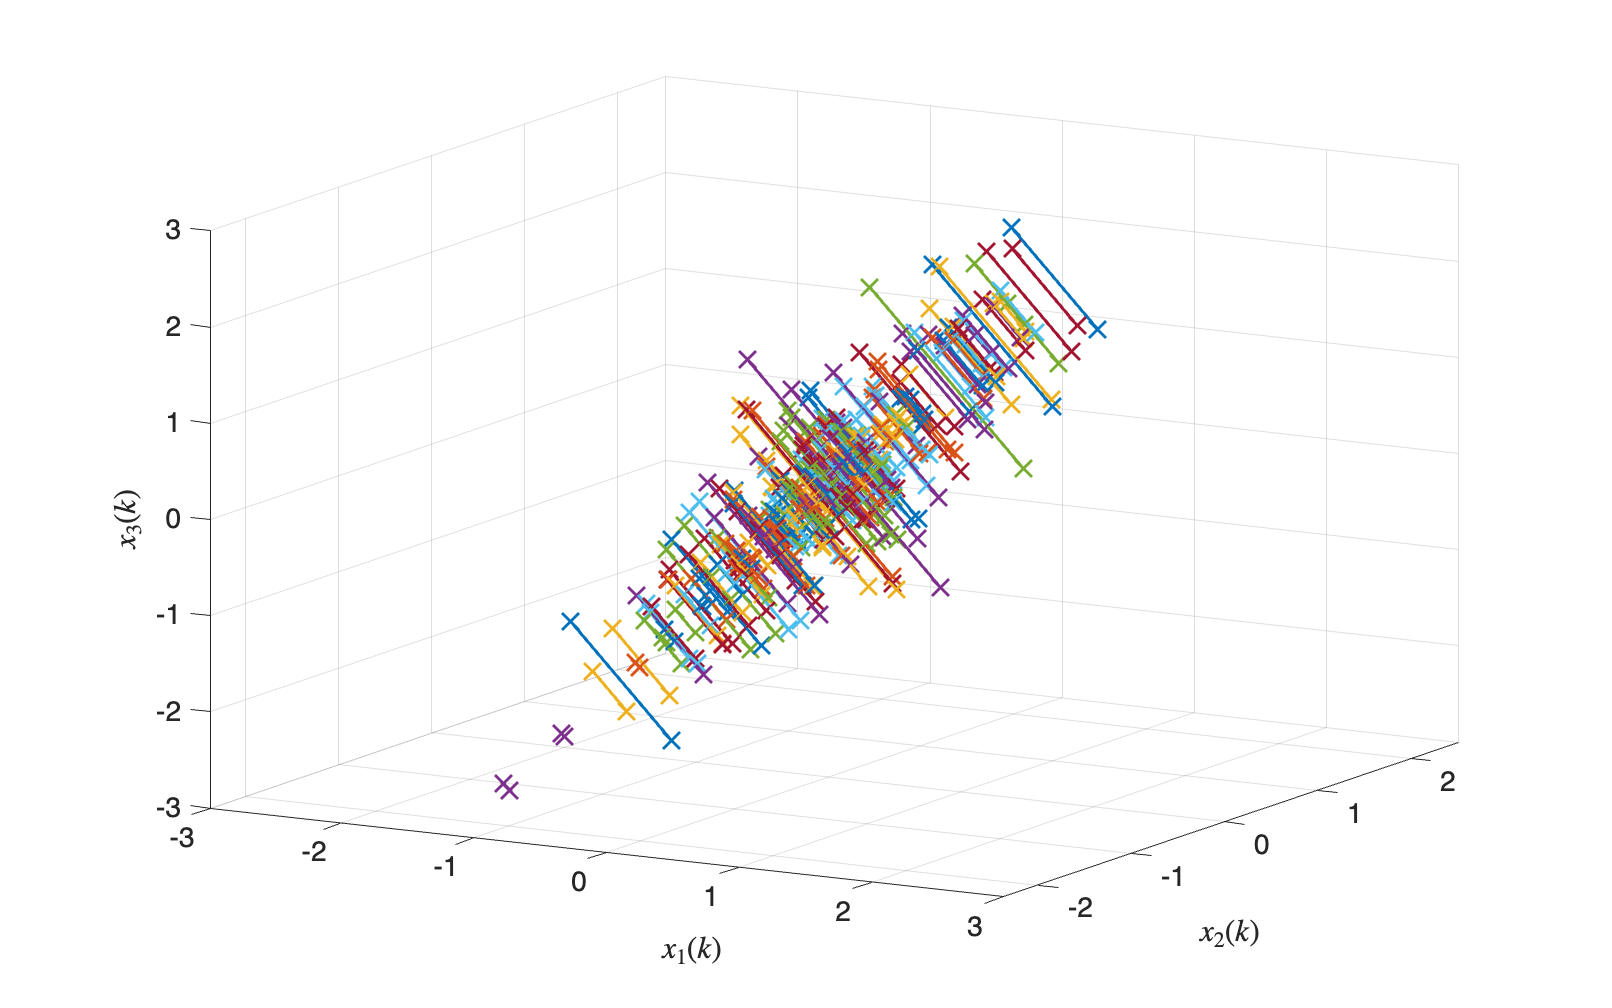

figure('Units','normalized', 'Position',[ 0.1, 0.1, 0.9, 0.9]);

for k=1:Ntrials
    Xvar = Xdata{k}; % retrieving the data from the storage set
    plot3( Xvar(:,1), Xvar(:,2), Xvar(:,3), '-x', 'LineWidth', 1.5, 'MarkerSize',12);
    hold on;
end % for k
grid on;
xlabel('$x_1(k)$', 'Interpreter','latex');
ylabel('$x_2(k)$', 'Interpreter','latex');
zlabel('$x_3(k)$', 'Interpreter','latex');
set(gca, 'Fontsize', 14);

I movimenti dello stato giacciono i una porzione dello spazio